# OTFS vs. OFDM and OTFS-IM vs. OFDM-IM at High Mobility

This live script runs two comparisons over a doubly dispersive 3GPP TDL-A channel at 500 km/h:

- **OTFS vs. OFDM:** plain QAM on every resource (no index modulation).

- **OTFS-IM vs. OFDM-IM:** plain index modulation (not IQ-IM). $a$ of the  $n$ resources in each group are active.

It also shows the IM mapping, the effective channel in each domain, the detection equations (Section 6), and the BER slope of every scheme.

Three receivers are used, each followed by group-wise LUT (minimum distance) detection:

- **OTFS, ICI-aware:** full-frame MIMO MMSE on the complete channel (all delay and Doppler terms), then detection in the delay-Doppler (DD) domain.

- **OFDM, ICI-aware:** the same full-frame MIMO MMSE criterion on the OFDM effective channel (including ICI), then detection in the time-frequency (TF) domain.

- **OFDM, one-tap:** the conventional OFDM receiver. A per-resource  $N_r\times N_t$ MMSE that uses only the diagonal of the TF channel and ignores ICI.

**Why the comparison is fair:**

- **Same channel and noise:** every frame uses the same physical channel (tap gains and Dopplers) and the same noise statistics for both waveforms.

- **Same IM and receivers:** the same LUT, group size and SNR definition (transmit power per resource over $N_0$), and the same MMSE + LUT receiver class for the ICI-aware OTFS and OFDM curves.

- **Conventional OFDM:** it uses a cyclic prefix that covers the delay spread and the fractional-delay filter, so at $v = 0$ its TF channel is exactly diagonal (checked in Section 5). Both OFDM receivers discard the CP, and the CP overhead is **not** charged to OFDM's SE. Both choices favour OFDM, so any remaining OTFS gain is conservative.

- **OTFS needs no CP:** its MMSE uses the full time-domain channel  $\mathbf{G}$. Because $\mathbf{A}_{\textrm{OTFS}}$ is unitary,


$$\left(\mathbf{A}^H\mathbf{G}^H\mathbf{G}\mathbf{A}+\lambda\mathbf{I}\right)^{-1}\mathbf{A}^H\mathbf{G}^H
 =\mathbf{A}^H\left(\mathbf{G}^H\mathbf{G}+\lambda\mathbf{I}\right)^{-1}\mathbf{G}^H ,$$


so time-domain MMSE followed by the SFFT is exactly DD-domain MMSE.

## 1. Parameters

clear; close all; rng(1);
quickTest = false;            % true -> very short run to check the script

% Frame / waveform
M  = 16;                      % delay bins (OTFS) = subcarriers (OFDM)
N  = 16;                      % Doppler bins (OTFS) = OFDM symbols
df = 15e3;                    % subcarrier spacing [Hz]
fc = 5e9;                     % carrier frequency [Hz]
v_kmh = 500;                  % user speed [km/h]

% MIMO
Nt = 2;  Nr = 2;

% Index modulation (plain IM): a of n = MG*NG resources active
MG = 2;  NG = 2;              % group = MG delay/subcarrier x NG Doppler/symbol
a  = 2;                       % active resources per group
Mmod = 4;                     % IM symbol alphabet: 2 (BPSK) or 4 (QPSK)
MmodPlain = 4;                % plain OTFS/OFDM alphabet on every resource

% Channel: 3GPP TR 38.901 TDL-A (normalized delays x DS), Jakes Doppler per tap
DS = 1e-6;                    % RMS delay spread [s]
sincHalf = 4;                 % fractional-delay (windowed-sinc) filter half-width
cpLen    = [];                % OFDM CP per symbol; [] -> just long enough (see below), 0 -> no CP

% Monte Carlo
SNRdB     = 0:4:28;
minErr    = 300;              % stop an SNR point after this many bit errors (all schemes)
maxFrames = 2000;             % ... or after this many frames (full run ~10 min)
if quickTest, SNRdB = [8 20]; minErr = 20; maxFrames = 4; end %#ok<UNRCH>

% Derived quantities
fs = M*df;  Lx = M*N;  n = MG*NG;  Groups = Lx/n;
fDmax = v_kmh/3.6*fc/3e8;
tauNorm = [0 0.3819 0.4025 0.5868 0.4610 0.5375 0.6708 0.5750 0.7618 1.5375 ...
           1.8978 2.2242 2.1718 2.4942 2.5119 3.0582 4.0810 4.4579 4.5695 ...
           4.7966 5.0066 5.0132 5.4467];
pwrdB   = [-13.4 0 -2.2 -4 -6 -8.2 -9.9 -10.5 -7.5 -15.9 -6.6 -16.7 -12.4 ...
           -15.2 -10.8 -11.3 -12.7 -16.2 -18.3 -18.9 -16.6 -14.9 -13.9];
pathPwr = 10.^(pwrdB/10);  pathPwr = pathPwr/sum(pathPwr);
delaysSamp = tauNorm*DS*fs;
P = numel(tauNorm);

% OFDM CP. The channel taps span sample shifts round(delay) - sincHalf ... round(delay) + sincHalf.
% The receiver FFT window is advanced by Koff = sincHalf samples, so a CP of
% length >= 2*sincHalf + round(max delay) makes every OFDM symbol ISI-free (circular).
if isempty(cpLen), cpLen = 2*sincHalf + round(max(delaysSamp)); end
Koff = min(sincHalf, cpLen);
Lt   = N*(M + cpLen);                 % OFDM frame length in samples (OTFS: Lx = M*N)

fprintf('Grid %d x %d, group %d x %d (n = %d), a = %d, %d-ary, %dx%d MIMO\n', ...
        M, N, MG, NG, n, a, Mmod, Nt, Nr);

Grid 16 x 16, group 2 x 2 (n = 4), a = 2, 4-ary, 2x2 MIMO


fprintf('fD,max = %.0f Hz, eps = fD/df = %.3f, Doppler bin = %.0f Hz (%.2f bins)\n', ...
        fDmax, fDmax/df, df/N, fDmax/(df/N));

fD,max = 2315 Hz, eps = fD/df = 0.154, Doppler bin = 938 Hz (2.47 bins)


fprintf('TDL-A: %d taps, DS = %.2f us, max delay = %.2f samples\n', P, DS*1e6, max(delaysSamp));

TDL-A: 23 taps, DS = 1.00 us, max delay = 1.31 samples


fprintf('OFDM CP = %d samples per symbol (overhead %.0f%%, not charged to OFDM SE); OTFS: no CP\n', ...
        cpLen, 100*cpLen/M);

OFDM CP = 9 samples per symbol (overhead 56%, not charged to OFDM SE); OTFS: no CP


## 2. IM mapping: look-up table and index patterns

Each group of $n$ resources carries


$$b = \underbrace{\left\lfloor \log_2 \binom{n}{a} \right\rfloor}_{\textrm{index bits}}
 + \underbrace{a \log_2 \mathcal{M}}_{\textrm{symbol bits}}$$


bits. Only the first $2^{b_1}$ activation patterns are used. The spectral efficiency per resource is $\eta = N_t\, b / n$, the same for OTFS and OFDM (the OFDM CP overhead is not charged).

[lut, bitMap, patterns, b1] = buildIMLUT(n, a, Mmod);
p = size(bitMap,1);  C = size(lut,2);
fprintf('IM: bits/group = %d (index %d + symbols %d), codewords C = %d, SE = %.3f bits/resource\n', ...
        p, b1, p-b1, C, Nt*p/n);

IM: bits/group = 6 (index 2 + symbols 4), codewords C = 64, SE = 3.000 bits/resource



% Plain OTFS/OFDM is the special case a = n: no index bits, all resources active.
% Per-group LUT detection is then exactly per-symbol ML slicing.
[lutP, bitMapP] = buildIMLUT(n, n, MmodPlain);
fprintf('Plain: %d-ary on every resource, SE = %.3f bits/resource\n', ...
        MmodPlain, Nt*log2(MmodPlain));

Plain: 4-ary on every resource, SE = 4.000 bits/resource



sch(1).name = "Plain";  sch(1).lut = lutP; sch(1).bitMap = bitMapP; sch(1).act = n;
sch(2).name = "IM";     sch(2).lut = lut;  sch(2).bitMap = bitMap;  sch(2).act = a;
for s = 1:2
    sch(s).p     = size(sch(s).bitMap, 1);
    sch(s).C     = size(sch(s).lut, 2);
    sch(s).scale = sqrt(n/(sch(s).act*Nt));      % tx amplitude: avg power 1/Nt per resource per antenna
    sch(s).SE    = Nt*sch(s).p/n;
end

posLabel = @(pp) sprintf('{%s}', strjoin(string(pp), ','));
IMtable = table(string(dec2bin(0:2^b1-1, max(b1,1))), ...
                arrayfun(@(k) string(posLabel(patterns(k,:))), (1:2^b1)'), ...
                'VariableNames', {'IndexBits', 'ActivePositions'});
disp(IMtable)

    IndexBits    ActivePositions
    _________    _______________

      "00"           "{1,2}"    
      "01"           "{1,3}"    
      "10"           "{1,4}"    
      "11"           "{2,3}"    



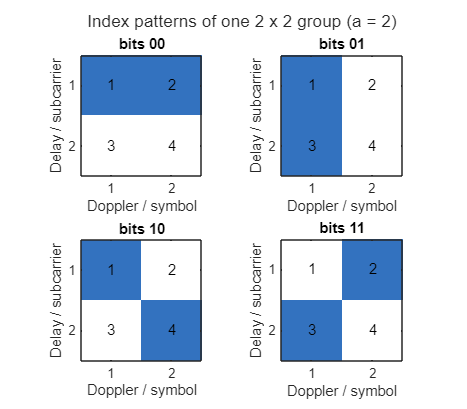


figure('Name','IM mapping','Color','w','Position',[100 100 480 420]);
tl = tiledlayout('flow', 'TileSpacing','compact');
title(tl, sprintf('Index patterns of one %d x %d group (a = %d)', MG, NG, a));
for k = 1:2^b1
    nexttile;
    blk = zeros(MG, NG);
    for pos = patterns(k,:)
        [d, f] = pos2df(pos, NG);  blk(d, f) = 1;
    end
    imagesc(blk, [0 1]); colormap(gca, [1 1 1; 0.20 0.45 0.75]);
    axis image; set(gca,'XTick',1:NG,'YTick',1:MG,'FontSize',10);
    xlabel('Doppler / symbol'); ylabel('Delay / subcarrier');
    title(sprintf('bits %s', dec2bin(k-1, max(b1,1))));
    for d = 1:MG
        for f = 1:NG
            text(f, d, num2str((d-1)*NG+f), 'HorizontalAlignment','center', 'FontSize',11);
        end
    end
end

## 3. Placing the groups: DD grid (OTFS) and TF grid (OFDM)

Both waveforms tile the $M\times N$ grid with the same $M_G\times N_G$ groups. In OTFS the grid is the DD domain and the transmit signal is $\mathbf{s}=\left(\mathbf{F}_N^H\otimes\mathbf{I}_M\right)\mathbf{x}$. In OFDM the grid is the TF domain and $\mathbf{s}=\left(\mathbf{I}_N\otimes\mathbf{F}_M^H\right)\mathbf{x}$, with a CP added to each OFDM symbol.

The middle panel is the key point. An OTFS-IM frame, viewed in the TF plane, spreads every DD symbol over all subcarriers and all OFDM symbols. An OFDM-IM symbol stays on one TF resource. This is the origin of the diversity difference.

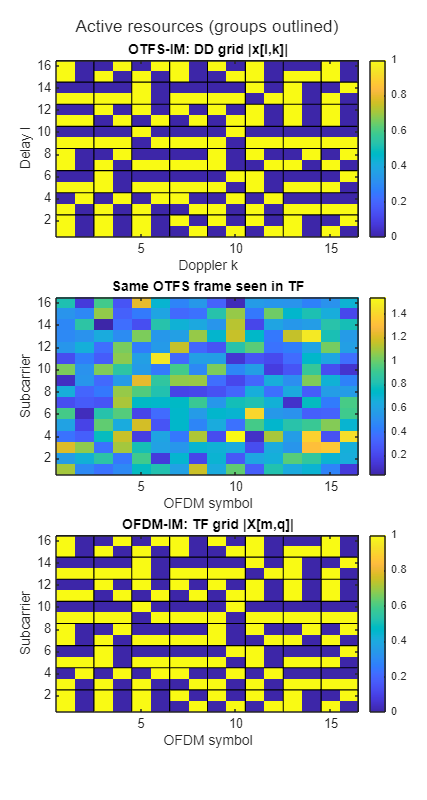

grpIdx = groupIndex(M, N, MG, NG);                 % n x Groups, linear indices
FM = fft(eye(M))/sqrt(M);  FN = fft(eye(N))/sqrt(N);
A_otfs = kron(FN', eye(M));                        % DD -> time
A_ofdm = kron(eye(N), FM');                        % TF -> time, no CP (TF view only)
% CP-OFDM: transmit matrix with CP, receive window (CP removed, advanced by
% Koff) and per-symbol DFT. Sw*Acp is a cyclic row shift of A_ofdm, so it is unitary.
FMh = FM';
Acp = kron(eye(N), [FMh(M-cpLen+1:M, :); FMh]);    % Lt x Lx
Sw  = kron(eye(N), [zeros(M, cpLen-Koff), eye(M), zeros(M, Koff)]);   % Lx x Lt
Dft = kron(eye(N), FM);                            % window time -> TF
ofdm = struct('Acp', Acp, 'Sw', Sw, 'Dft', Dft, 'Lt', Lt);

cwEx = randi(C, Groups, 1);
Xex  = zeros(Lx,1);  Xex(grpIdx(:)) = reshape(lut(:, cwEx), [], 1);
Xtf_of_otfs = A_ofdm' * (A_otfs * Xex);            % TF view of the OTFS frame

figure('Name','Mapping on the grid','Color','w','Position',[100 50 480 900]);
tl = tiledlayout(3,1,'TileSpacing','compact');
nexttile; showGrid(abs(reshape(Xex,M,N)), MG, NG);
title('OTFS-IM: DD grid |x[l,k]|'); xlabel('Doppler k'); ylabel('Delay l');
nexttile; imagesc(abs(reshape(Xtf_of_otfs,M,N))); axis xy; colorbar;
title('Same OTFS frame seen in TF'); xlabel('OFDM symbol'); ylabel('Subcarrier');
nexttile; showGrid(abs(reshape(Xex,M,N)), MG, NG);
title('OFDM-IM: TF grid |X[m,q]|'); xlabel('OFDM symbol'); ylabel('Subcarrier');
title(tl, 'Active resources (groups outlined)');

## 4. The channel each waveform sees

One realization of the 500 km/h TDL-A link, shown as the effective channel matrix in each domain (magnitude in dB):

- **DD (OTFS):** energy lies on a limited set of shifted diagonals, one band per delay/Doppler tap. Fractional Doppler (Jakes) and fractional delays spread each band into neighbouring bins, but the structure is the same for every DD symbol: each symbol sees all taps.

- **TF (CP-OFDM):** a strong main diagonal, with off-diagonal ICI energy inside each OFDM symbol (the 16 x 16 blocks). The CP removes inter-symbol interference, so this ICI comes from Doppler only. The one-tap receiver keeps only the diagonal; the ICI-aware receiver uses the whole matrix.

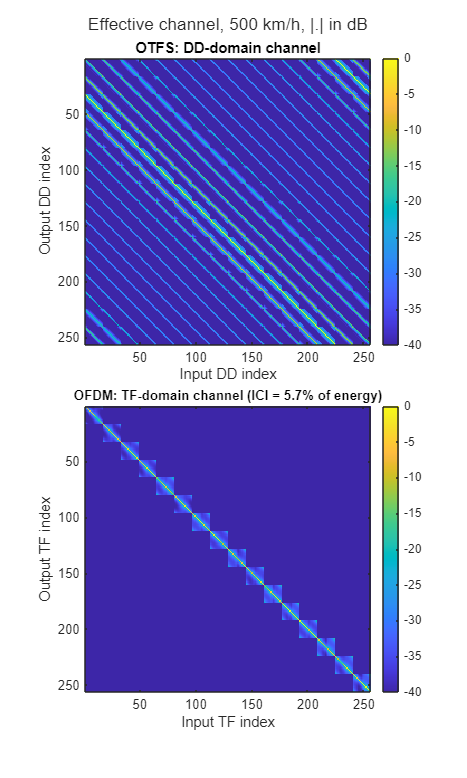

gEx  = sqrt(pathPwr/2).*(randn(1,P)+1j*randn(1,P));
fdEx = fDmax*cos(2*pi*rand(1,P));
Hdd  = A_otfs' * buildLinkG(Lx, fs, delaysSamp, gEx, fdEx, sincHalf) * A_otfs;
Htf  = Dft * Sw * buildLinkG(Lt, fs, delaysSamp, gEx, fdEx, sincHalf) * Acp;
dBclip = @(H) max(20*log10(abs(H)/max(abs(H(:)))), -40);
offDiagPct = 100*(1 - sum(abs(diag(Htf)).^2)/sum(abs(Htf(:)).^2));

figure('Name','Effective channels','Color','w','Position',[100 50 480 800]);
tl = tiledlayout(2,1,'TileSpacing','compact');
nexttile; imagesc(dBclip(Hdd)); axis image; colorbar; clim([-40 0]);
title('OTFS: DD-domain channel'); xlabel('Input DD index'); ylabel('Output DD index');
nexttile; imagesc(dBclip(Htf)); axis image; colorbar; clim([-40 0]);
title(sprintf('OFDM: TF-domain channel (ICI = %.1f%% of energy)', offDiagPct), 'FontSize', 10);
xlabel('Input TF index'); ylabel('Output TF index');
title(tl, sprintf('Effective channel, %d km/h, |.| in dB', v_kmh));

## 5. Self-checks

These checks run before the Monte Carlo simulation and stop the script if anything in the chain is wrong.

- **Unitary transforms:** $\mathbf{A}_{\textrm{OTFS}}$ and the CP-OFDM chain (CP insertion, CP removal, DFT) are unitary. So noise stays white and each waveform differs only in its basis.

- **OTFS equalizer:** time-domain MMSE followed by the SFFT equals MMSE on the DD effective channel (the identity stated at the top).

- **Power normalization:** the average transmit power per resource, summed over antennas, is $1$ for every scheme. So $\textrm{SNR}=1/N_0$ per receive antenna.

- **Clean channel:** a flat, static MIMO channel with negligible noise must give zero bit errors for every scheme and receiver (mapping, equalization, demodulation and LUT demapping all consistent).

- **CP and ICI:** the CP-OFDM TF channel must be exactly diagonal at  $v=0$, so the CP is long enough. At $v$ km/h the off-diagonal energy is then pure Doppler ICI.

% (1) unitary transforms
eU = [norm(A_otfs'*A_otfs - eye(Lx), 'fro'), norm((Sw*Acp)'*(Sw*Acp) - eye(Lx), 'fro'), ...
      norm(Dft'*Dft - eye(Lx), 'fro')];
fprintf('(1) unitarity error: OTFS %.1e, CP-OFDM window %.1e, DFT %.1e\n', eU);

(1) unitarity error: OTFS 1.4e-15, CP-OFDM window 1.4e-15, DFT 1.4e-15


assert(all(eU < 1e-9), 'Transform matrices are not unitary.');

% (2) OTFS: time-domain MMSE + SFFT == DD-domain MMSE
Gt  = drawMIMOChannel(Nt, Nr, Lx, Lt, fs, delaysSamp, pathPwr, fDmax, sincHalf);
rt  = randn(Nr*Lx,1) + 1j*randn(Nr*Lx,1);  lam = 0.05;
Ab  = kron(eye(Nt), A_otfs);  He = Gt*Ab;
x1  = Ab' * ((Gt'*Gt + lam*eye(Nt*Lx)) \ (Gt'*rt));
x2  = (He'*He + lam*eye(Nt*Lx)) \ (He'*rt);
eM  = norm(x1 - x2)/norm(x2);
fprintf('(2) OTFS: time-domain MMSE vs. DD-domain MMSE, relative difference %.1e\n', eM);

(2) OTFS: time-domain MMSE vs. DD-domain MMSE, relative difference 4.3e-15


assert(eM < 1e-8, 'OTFS equalizer identity failed.');

% (3) power normalization
pw = zeros(2,2);
for s = 1:2
    cwT = randi(sch(s).C, Groups, Nt);  XT = zeros(Lx, Nt);
    for t = 1:Nt, XT(grpIdx(:),t) = reshape(sch(s).lut(:,cwT(:,t)), [], 1) * sch(s).scale; end
    pw(s,:) = [sum(mean(abs(A_otfs*XT).^2,1)), sum(mean(abs(Acp*XT).^2,1))];
end
fprintf('(3) tx power per resource (sum over antennas): Plain OTFS %.3f OFDM %.3f | IM OTFS %.3f OFDM %.3f\n', pw.');

(3) tx power per resource (sum over antennas): Plain OTFS 1.000 OFDM 1.011 | IM OTFS 1.000 OFDM 0.997


assert(all(abs(pw(:) - 1) < 0.25), 'Power normalization is off.');

% (4) clean channel, negligible noise -> zero errors
H0 = eye(Nr, Nt) + 0.3*(randn(Nr,Nt) + 1j*randn(Nr,Nt))/sqrt(2);
[e0, nb0] = runFrame(kron(H0, eye(Lx)), kron(H0, eye(Lt)), 1e-10, 1e-10*Nt, ...
                     sch, grpIdx, A_otfs, ofdm, Nt, Nr, Groups);
fprintf('(4) flat static channel, noise-free: bit errors = %d of %d (all schemes/receivers)\n', ...
        sum(e0(:)), 3*sum(nb0));

(4) flat static channel, noise-free: bit errors = 0 of 5376 (all schemes/receivers)


assert(all(e0(:) == 0), 'Errors on a clean channel: the chain is inconsistent.');

% (5) CP-OFDM TF channel: off-diagonal energy at 0 km/h and at v km/h
nReal = 20;  offE = zeros(1,2);  vList = [0 v_kmh];
for iv = 1:2
    fD = vList(iv)/3.6*fc/3e8;
    for it = 1:nReal
        g  = sqrt(pathPwr/2).*(randn(1,P)+1j*randn(1,P));
        Hl = Dft * Sw * buildLinkG(Lt, fs, delaysSamp, g, fD*cos(2*pi*rand(1,P)), sincHalf) * Acp;
        offE(iv) = offE(iv) + (1 - sum(abs(diag(Hl)).^2)/sum(abs(Hl(:)).^2))/nReal;
    end
end
fprintf('(5) CP-OFDM off-diagonal energy: %.1e%% at 0 km/h, %.2f%% at %d km/h (Doppler ICI)\n', ...
        100*offE(1), 100*offE(2), v_kmh);

(5) CP-OFDM off-diagonal energy: 0.0e+00% at 0 km/h, 3.90% at 500 km/h (Doppler ICI)


if cpLen >= 2*sincHalf + round(max(delaysSamp))
    assert(offE(1) < 1e-10, 'CP too short: OFDM is not ISI/ICI-free at 0 km/h.');
end
fprintf('All self-checks passed.\n');

All self-checks passed.


## 6. Detection equations

This section lists what each receiver computes. The code is in `runFrame` and `detectGroups` at the end of the script.

**Notation**

- $\mathbf{x}\in\mathbf{C}^{N_tMN\times 1}$: transmitted symbols of all antennas, in the DD domain for OTFS and in the TF domain for OFDM.

- $\mathbf{G}$: time-domain MIMO channel with all delays and Dopplers.

- $\mathbf{w}$: noise with variance $N_0$ per sample.

- $\lambda=N_0N_t$: MMSE regularizer, because each antenna sends power  $1/N_t$ per resource.

- $\kappa=\sqrt{n/(aN_t)}$: transmit amplitude scaling ($a=n$ for plain QAM).

- $\mathbf{u}_c$: codeword number $c$ of the LUT, $c=1,\ldots,C$.

- $\mathcal{I}_g$: the $n$ grid positions of group $g$.

**Step 1, receiver 1: OTFS with full-channel MMSE**

The received signal, with $\mathbf{A}=\mathbf{F}_N^H\otimes\mathbf{I}_M$, is


$$\mathbf{r}=\mathbf{G}\left(\mathbf{I}_{N_t}\otimes\mathbf{A}\right)\mathbf{x}+\mathbf{w} .$$


The time-domain signal is equalized, then returned to the DD domain:


$$\hat{\mathbf{s}}=\left(\mathbf{G}^H\mathbf{G}+\lambda\mathbf{I}\right)^{-1}\mathbf{G}^H\mathbf{r} ,$$



$$\hat{\mathbf{x}}=\left(\mathbf{I}_{N_t}\otimes\mathbf{A}^H\right)\hat{\mathbf{s}} .$$


**Step 1, receiver 2: OFDM with full-channel (ICI-aware) MMSE**

Let $\mathbf{A}_{cp}$ add the CP and apply the IDFT, and let $\mathbf{S}_w$ keep the receive window (CP removed). With $\mathbf{G}_c$ the channel over the longer CP-OFDM frame,


$$\mathbf{H}_o=\left(\mathbf{I}_{N_r}\otimes\mathbf{S}_w\right)\mathbf{G}_c\left(\mathbf{I}_{N_t}\otimes\mathbf{A}_{cp}\right) ,$$



$$\mathbf{r}_o=\mathbf{H}_o\mathbf{x}+\mathbf{w}_o ,$$



$$\hat{\mathbf{x}}=\left(\mathbf{H}_o^H\mathbf{H}_o+\lambda\mathbf{I}\right)^{-1}\mathbf{H}_o^H\mathbf{r}_o .$$


**Step 1, receiver 3: OFDM with one-tap MMSE**

After the DFT, resource $k$ carries the wanted symbol plus ICI:


$$\mathbf{y}_k=\mathbf{H}_{k,k}\mathbf{x}_k+\sum_{k'\neq k}\mathbf{H}_{k,k'}\mathbf{x}_{k'}+\mathbf{w}_k .$$


The one-tap receiver uses only $\mathbf{H}_{k,k}$ ($N_r\times N_t$) and ignores the sum:


$$\hat{\mathbf{x}}_k=\left(\mathbf{H}_{k,k}^H\mathbf{H}_{k,k}+\lambda\mathbf{I}_{N_t}\right)^{-1}\mathbf{H}_{k,k}^H\mathbf{y}_k .$$


The ICI sum grows with the signal power, so a higher SNR does not remove it. This is the origin of the error floor.

**Step 2, all receivers: LUT detection of each group**

The equalized samples of group $g$ on antenna $t$ are


$$\mathbf{z}_{g,t}=\hat{\mathbf{x}}_t[\mathcal{I}_g]/\kappa .$$


The detected codeword is the nearest one in the LUT:


$$\hat{c}_{g,t}=\arg\min_{c}\left\|\mathbf{z}_{g,t}-\mathbf{u}_c\right\|^2 .$$


The code uses the expanded form, where the first term does not depend on $c$:


$$\left\|\mathbf{z}-\mathbf{u}_c\right\|^2=\left\|\mathbf{z}\right\|^2+\left\|\mathbf{u}_c\right\|^2-2\Re\left\{\mathbf{z}^H\mathbf{u}_c\right\} .$$


The codeword index gives the index bits and the symbol bits together. For plain QAM ($a=n$) this step is ordinary symbol-by-symbol slicing.

**What this is not: true ML**

Exact ML would compare all possible frames jointly,


$$\hat{\mathbf{x}}_{ML}=\arg\min_{\mathbf{x}}\left\|\mathbf{r}-\mathbf{G}\left(\mathbf{I}_{N_t}\otimes\mathbf{A}\right)\mathbf{x}\right\|^2 ,$$


which needs $C^{N_tMN/n}$ candidates ($64^{128}$ for IM with the default settings). The MMSE step replaces this search. Two approximations follow: the interference left after MMSE is treated as white noise, and the MMSE amplitude bias is not removed before the LUT search.

## 7. BER simulation

For each frame: draw a new channel (one set of tap gains and Dopplers, evaluated over the OTFS frame and over the slightly longer CP-OFDM frame). Then, for both schemes (plain and IM), map random codewords on every antenna, transmit with OTFS and with CP-OFDM, and detect with the three receivers (function `runFrame` at the end of the script). The MMSE factorizations and the one-tap channel are computed once per channel and shared by both schemes. Tx SNR is the total transmit power per resource divided by the noise power $N_0$.

rxNames = ["OTFS (ICI-aware MMSE)", "OFDM (ICI-aware MMSE)", "OFDM (one-tap MMSE)"];
ber = nan(2, 3, numel(SNRdB));                     % scheme x receiver x SNR
nFr = zeros(1, numel(SNRdB));
tic;
for si = 1:numel(SNRdB)
    N0  = 10^(-SNRdB(si)/10);
    reg = N0*Nt;                              % MMSE regularizer: N0 / (per-antenna power 1/Nt)
    err = zeros(2,3);  nbits = zeros(2,1);  fr = 0;
    while fr < maxFrames && min(err(:)) < minErr
        fr = fr + 1;
        [Gx, Gc] = drawMIMOChannel(Nt, Nr, Lx, Lt, fs, delaysSamp, pathPwr, fDmax, sincHalf);
        [e, nb] = runFrame(Gx, Gc, N0, reg, sch, grpIdx, A_otfs, ofdm, Nt, Nr, Groups);
        err = err + e;  nbits = nbits + nb;
    end
    ber(:, :, si) = err ./ nbits;  nFr(si) = fr;
    fprintf(['SNR %2d dB | %3d frames | Plain: OTFS %.1e OFDM-ICI %.1e OFDM-1tap %.1e' ...
             ' | IM: OTFS %.1e OFDM-ICI %.1e OFDM-1tap %.1e\n'], SNRdB(si), fr, ...
            ber(1,1,si), ber(1,2,si), ber(1,3,si), ber(2,1,si), ber(2,2,si), ber(2,3,si));
end

SNR  0 dB |   2 frames | Plain: OTFS 2.4e-01 OFDM-ICI 2.6e-01 OFDM-1tap 2.7e-01 | IM: OTFS 3.3e-01 OFDM-ICI 3.2e-01 OFDM-1tap 3.1e-01
SNR  4 dB |   3 frames | Plain: OTFS 1.4e-01 OFDM-ICI 1.5e-01 OFDM-1tap 1.6e-01 | IM: OTFS 1.8e-01 OFDM-ICI 1.8e-01 OFDM-1tap 2.0e-01
SNR  8 dB |   7 frames | Plain: OTFS 5.9e-02 OFDM-ICI 7.0e-02 OFDM-1tap 8.8e-02 | IM: OTFS 5.6e-02 OFDM-ICI 7.9e-02 OFDM-1tap 9.0e-02
SNR 12 dB |  28 frames | Plain: OTFS 2.6e-02 OFDM-ICI 3.5e-02 OFDM-1tap 5.6e-02 | IM: OTFS 1.5e-02 OFDM-ICI 3.6e-02 OFDM-1tap 5.8e-02
SNR 16 dB | 244 frames | Plain: OTFS 4.4e-03 OFDM-ICI 1.4e-02 OFDM-1tap 3.8e-02 | IM: OTFS 1.6e-03 OFDM-ICI 1.1e-02 OFDM-1tap 3.6e-02
SNR 20 dB | 2000 frames | Plain: OTFS 4.1e-04 OFDM-ICI 5.6e-03 OFDM-1tap 3.1e-02 | IM: OTFS 6.1e-05 OFDM-ICI 3.7e-03 OFDM-1tap 3.0e-02
SNR 24 dB | 2000 frames | Plain: OTFS 1.8e-05 OFDM-ICI 2.2e-03 OFDM-1tap 2.9e-02 | IM: OTFS 6.5e-07 OFDM-ICI 1.3e-03 OFDM-1tap 3.0e-02
SNR 28 dB | 2000 frames | Plain: OTFS 1.5e-06 OFDM-ICI 8.6e-

fprintf('Simulation time: %.1f s\n', toc);

Simulation time: 517.9 s


fprintf(['Note: points with 0 errors are not plotted; the smallest measurable BER at an ' ...
         'SNR point is about 1/(bits simulated).\n']);

Note: points with 0 errors are not plotted; the smallest measurable BER at an SNR point is about 1/(bits simulated).


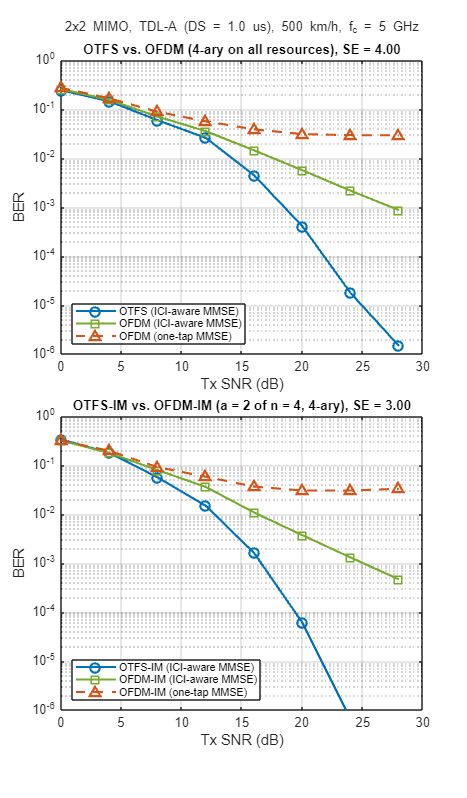


mk  = {'-o', '-s', '--^'};
col = [0 0.447 0.741; 0.466 0.674 0.188; 0.850 0.325 0.098];
ttl = [sprintf("OTFS vs. OFDM (%d-ary on all resources), SE = %.2f", MmodPlain, sch(1).SE), ...
       sprintf("OTFS-IM vs. OFDM-IM (a = %d of n = %d, %d-ary), SE = %.2f", a, n, Mmod, sch(2).SE)];
pre = ["", "-IM"];

figure('Name','BER','Color','w','Position',[100 50 480 820]);
tl = tiledlayout(2,1,'TileSpacing','compact');
for s = 1:2
    nexttile;
    for q = 1:3
        b = squeeze(ber(s,q,:)).';  b(b==0) = NaN;
        semilogy(SNRdB, b, mk{q}, 'Color', col(q,:), 'LineWidth', 1.6, 'MarkerSize', 7); hold on;
    end
    grid on; ylim([1e-6 1]); xlabel('Tx SNR (dB)'); ylabel('BER');
    legend(replace(rxNames, ["OTFS ", "OFDM "], ["OTFS"+pre(s)+" ", "OFDM"+pre(s)+" "]), ...
           'Location', 'southwest', 'FontSize', 8);
    title(ttl(s), 'FontSize', 10);
end
title(tl, sprintf('%dx%d MIMO, TDL-A (DS = %.1f us), %d km/h, f_c = %.0f GHz', ...
      Nt, Nr, DS*1e6, v_kmh, fc/1e9), 'FontSize', 10);

## 8. Diversity (BER slope)

The diversity order is the high-SNR slope of the BER curve,


$$d = -\lim_{\textrm{SNR}\to\infty}\frac{\log_{10}\textrm{BER}}{\log_{10}\textrm{SNR}} .$$


For each comparison (plain first, then IM) there is one figure with two plots. The first is the BER with reference slopes $\textrm{SNR}^{-d}$ for $d=1,2,3$, anchored at the last OTFS point. The second is the local slope between adjacent SNR points,


$$\hat{d}=-\frac{\Delta\log_{10}\textrm{BER}}{\Delta(\textrm{SNR}_{\textrm{dB}}/10)} .$$


How to read it:

- **One-tap OFDM** flattens and $\hat d\to 0$: an error floor caused by unmodelled ICI.

- **ICI-aware OFDM** has no floor. Its slope stays near $1$, because each OFDM symbol sees one fading coefficient: the Doppler spread is far below the subcarrier spacing and the TDL-A delays are about one sample.

- **OTFS** is steeper. Each DD symbol spreads over the whole TF frame and sees every resolvable delay and Doppler tap.

- **IM vs. plain:** IM runs at a lower SE here (3 vs. 4 bits per resource), so compare OTFS with OFDM inside a panel, not IM with plain across panels.

**Limits of this plot:**

- The slopes are **finite-SNR** slopes of linear MMSE + LUT receivers, not asymptotic diversity orders.

- A BER point with few bit errors is unreliable. With the default settings the last OTFS points rest on about 3 errors (plain, 28 dB) and 1 error (IM, 24 dB), so do not quote the slopes there. Raise `maxFrames` to improve them.

- The 0 to 12 dB points use only 2 to 28 channel realizations, so small bumps in the slope at low SNR are not meaningful.

- The d = 1, 2, 3 lines show steepness only. Their position is arbitrary.

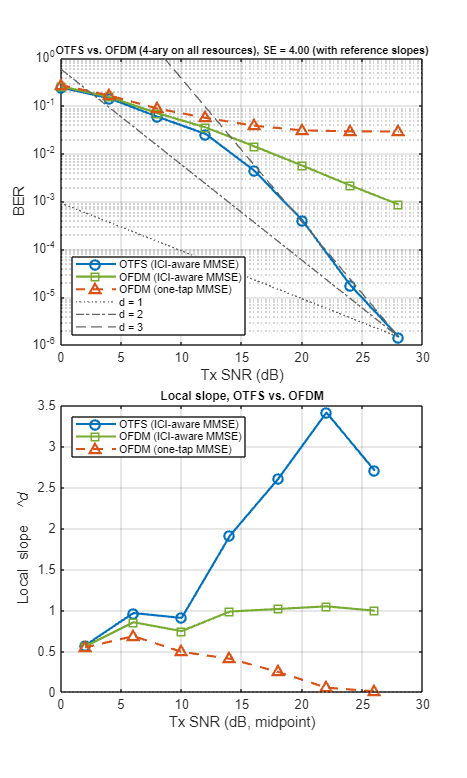

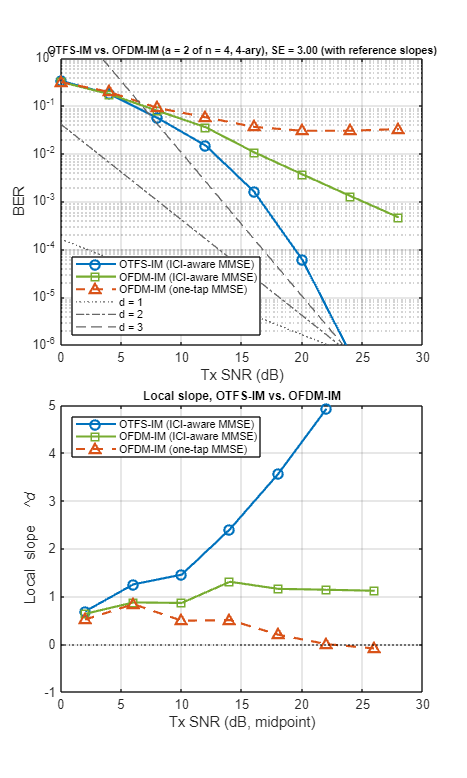

for s = 1:2
    figure('Name',"Diversity " + sch(s).name,'Color','w','Position',[100 50 480 800]);
    tl = tiledlayout(2,1,'TileSpacing','compact');
    names = replace(rxNames, ["OTFS ", "OFDM "], ["OTFS"+pre(s)+" ", "OFDM"+pre(s)+" "]);
    nexttile;
    for q = 1:3
        b = squeeze(ber(s,q,:)).';  b(b==0) = NaN;
        semilogy(SNRdB, b, mk{q}, 'Color', col(q,:), 'LineWidth', 1.6, 'MarkerSize', 7); hold on;
    end
    refNames = strings(0);
    valid = find(squeeze(ber(s,1,:)) > 0, 1, 'last');
    if ~isempty(valid)
        s0 = SNRdB(valid);  b0 = ber(s,1,valid);
        sr = linspace(SNRdB(1), SNRdB(end), 50);
        ls = {':', '-.', '--'};
        for d = 1:3
            semilogy(sr, b0*10.^(-d*(sr - s0)/10), ls{d}, 'Color', [0.4 0.4 0.4], 'LineWidth', 1);
        end
        refNames = ["d = 1", "d = 2", "d = 3"];
    end
    grid on; ylim([1e-6 1]); xlabel('Tx SNR (dB)'); ylabel('BER');
    legend([names refNames], 'Location', 'southwest', 'FontSize', 8);
    title(ttl(s) + " (with reference slopes)", 'FontSize', 8);

    nexttile;
    for q = 1:3
        b = squeeze(ber(s,q,:)).';  b(b<=0) = NaN;
        dHat = -diff(log10(b)) ./ diff(SNRdB/10);
        plot(SNRdB(1:end-1) + diff(SNRdB)/2, dHat, mk{q}, 'Color', col(q,:), ...
             'LineWidth', 1.6, 'MarkerSize', 7); hold on;
    end
    yline(0, 'k:'); grid on;
    xlabel('Tx SNR (dB, midpoint)'); ylabel('Local slope  \it\^d');
    legend(names, 'Location', 'northwest', 'FontSize', 8);
    title("Local slope, " + names(1).extractBefore(" ") + " vs. " + names(2).extractBefore(" "), 'FontSize', 9);
end


schemeNames = [sch.name];  SE = [sch.SE];
save('OFDM_vs_OTFS_IM_results.mat', 'SNRdB', 'ber', 'rxNames', 'schemeNames', 'SE', 'M', 'N', ...
     'MG', 'NG', 'a', 'Mmod', 'MmodPlain', 'Nt', 'Nr', 'v_kmh', 'fc', 'df', 'DS', 'cpLen', 'nFr');

## Local functions

function [Gx, Gc] = drawMIMOChannel(Nt, Nr, Lx, Lt, fs, delaysSamp, pathPwr, fDmax, sincHalf)
% One TDL-A MIMO realization: independent Rayleigh tap gains per link, one
% Jakes Doppler per tap shared by all links (same scatterers). The same
% physical channel is evaluated over the OTFS frame (Lx samples) and over
% the CP-OFDM frame (Lt samples).
P   = numel(delaysSamp);
fds = fDmax*cos(2*pi*rand(1,P));
Gx  = zeros(Nr*Lx, Nt*Lx);  Gc = zeros(Nr*Lt, Nt*Lt);
for r = 1:Nr
    for t = 1:Nt
        g = sqrt(pathPwr/2).*(randn(1,P) + 1j*randn(1,P));
        Gx((r-1)*Lx+(1:Lx), (t-1)*Lx+(1:Lx)) = buildLinkG(Lx, fs, delaysSamp, g, fds, sincHalf);
        if nargout > 1
            Gc((r-1)*Lt+(1:Lt), (t-1)*Lt+(1:Lt)) = buildLinkG(Lt, fs, delaysSamp, g, fds, sincHalf);
        end
    end
end
end

function [err, nbits] = runFrame(Gx, Gc, N0, reg, sch, grpIdx, A_otfs, ofdm, Nt, Nr, Groups)
% One frame for every scheme (Plain, IM) and receiver:
%   1 OTFS ICI-aware, 2 CP-OFDM ICI-aware, 3 CP-OFDM one-tap.
% OTFS:    r = Gx * (A_otfs x) + w,           MMSE in time domain, then SFFT.
% CP-OFDM: r = Gc * (Acp X) + w, keep window Sw*r (CP removed).
%          Effective channel Ho = Sw Gc Acp (TF input -> window time output).
Lx = size(A_otfs, 1);  Lt = ofdm.Lt;
SwR = kron(eye(Nr), ofdm.Sw);
Ho  = SwR * Gc * kron(eye(Nt), ofdm.Acp);          % (Nr*Lx) x (Nt*Lx), includes ICI
Rx  = chol(Gx'*Gx + reg*eye(Nt*Lx));               % OTFS ICI-aware MMSE
Ro  = chol(Ho'*Ho + reg*eye(Nt*Lx));               % OFDM ICI-aware MMSE
Hk  = zeros(Nr, Nt, Lx);                           % OFDM one-tap: diag of Dft*Ho_rt
for r = 1:Nr
    for t = 1:Nt
        Hrt = ofdm.Dft * Ho((r-1)*Lx+(1:Lx), (t-1)*Lx+(1:Lx));
        Hk(r,t,:) = diag(Hrt);
    end
end
Wk = zeros(Nt, Nr, Lx);
for k = 1:Lx
    H = Hk(:,:,k);
    Wk(:,:,k) = (H'*H + reg*eye(Nt)) \ H';
end
wx = sqrt(N0/2)*(randn(Nr*Lx,1) + 1j*randn(Nr*Lx,1));
wc = sqrt(N0/2)*(randn(Nr*Lt,1) + 1j*randn(Nr*Lt,1));

err = zeros(numel(sch), 3);  nbits = zeros(numel(sch), 1);
for s = 1:numel(sch)
    S  = sch(s);
    cw = randi(S.C, Groups, Nt);
    X  = zeros(Lx, Nt);
    for t = 1:Nt
        X(grpIdx(:), t) = reshape(S.lut(:, cw(:,t)), [], 1) * S.scale;
    end
    r_otfs = Gx*reshape(A_otfs*X, [], 1) + wx;
    r_ofdm = SwR*(Gc*reshape(ofdm.Acp*X, [], 1) + wc);   % CP removed

    Xh = cell(3,1);
    Xh{1} = A_otfs' * reshape(Rx \ (Rx' \ (Gx'*r_otfs)), Lx, Nt) / S.scale;
    Xh{2} = reshape(Ro \ (Ro' \ (Ho'*r_ofdm)), Lx, Nt) / S.scale;
    Y  = ofdm.Dft * reshape(r_ofdm, Lx, Nr);       % Lx x Nr (TF, per rx antenna)
    X1 = zeros(Lx, Nt);
    for k = 1:Lx
        X1(k,:) = (Wk(:,:,k) * Y(k,:).').';
    end
    Xh{3} = X1 / S.scale;

    for q = 1:3
        cwHat = detectGroups(Xh{q}, grpIdx, S.lut);
        err(s,q) = nnz(S.bitMap(:, cwHat(:)) ~= S.bitMap(:, cw(:)));
    end
    nbits(s) = S.p*Groups*Nt;
end
end


function [lut, bitMap, patterns, b1] = buildIMLUT(n, a, Mmod)
% Plain IM LUT: first 2^b1 activation patterns x all Mmod^a symbol vectors.
allPat   = nchoosek(1:n, a);
b1       = floor(log2(size(allPat,1)));
patterns = allPat(1:2^b1, :);
m        = log2(Mmod);
symIdx   = dec2base(0:Mmod^a-1, Mmod, a) - '0';      % (Mmod^a) x a, MSB first
C        = 2^b1 * Mmod^a;
lut      = zeros(n, C);
bitMap   = zeros(b1 + a*m, C);
c = 0;
for ip = 1:2^b1
    for is = 1:Mmod^a
        c = c + 1;
        bits = dec2bin(ip-1, max(b1,1)) - '0';
        bits = bits(end-b1+1:end);
        for k = 1:a
            sb = dec2bin(symIdx(is,k), m) - '0';
            lut(patterns(ip,k), c) = mapSym(sb, Mmod);
            bits = [bits sb];                            %#ok<AGROW>
        end
        bitMap(:, c) = bits(:);
    end
end
end

function s = mapSym(b, Mmod)
% Gray BPSK / QPSK with unit energy.
if Mmod == 2
    s = 1 - 2*b(1);
elseif Mmod == 4
    s = ((1 - 2*b(1)) + 1j*(1 - 2*b(2)))/sqrt(2);
else
    error('Only BPSK (2) and QPSK (4) are implemented.');
end
end

function [d, f] = pos2df(pos, NG)
% LUT position (1..n) -> (delay/subcarrier d, Doppler/symbol f) inside a group.
d = floor((pos-1)/NG) + 1;
f = pos - (d-1)*NG;
end

function idx = groupIndex(M, N, MG, NG)
% n x Groups linear indices into the M x N grid (column-major), block mapping.
n = MG*NG;  idx = zeros(n, (M/MG)*(N/NG));  g = 0;
for gn = 0:N/NG-1
    for gm = 0:M/MG-1
        g = g + 1;
        for pos = 1:n
            [d, f] = pos2df(pos, NG);
            idx(pos, g) = (gm*MG + d) + M*(gn*NG + f - 1);
        end
    end
end
end

function G = buildLinkG(Lx, fs, delaysSamp, gains, fds, sincHalf)
% Time-domain Lx x Lx channel: fractional delay (windowed sinc) and a
% per-tap Doppler phase ramp along the input index.
G = zeros(Lx, Lx);
i = (0:Lx-1).';
for pth = 1:numel(delaysSamp)
    dp   = delaysSamp(pth);
    ramp = gains(pth) * exp(1j*2*pi*fds(pth)*i/fs);
    k0   = round(dp);
    for k = k0-sincHalf : k0+sincHalf
        w = sincLocal(k - dp);
        if w == 0, continue; end
        rows = i + k;  ok = rows >= 0 & rows < Lx;
        lin  = (rows(ok)+1) + Lx*i(ok);
        G(lin) = G(lin) + w*ramp(ok);
    end
end
end

function y = sincLocal(x)
y = ones(size(x));  nz = x ~= 0;
y(nz) = sin(pi*x(nz))./(pi*x(nz));
end

function cwHat = detectGroups(Xh, grpIdx, lut)
% Group-wise minimum-distance LUT detection for every antenna stream.
Nt = size(Xh, 2);  Groups = size(grpIdx, 2);
cwHat = zeros(Groups, Nt);
lutE  = sum(abs(lut).^2, 1);
for t = 1:Nt
    Yg = reshape(Xh(grpIdx(:), t), size(grpIdx));          % n x Groups
    D  = sum(abs(Yg).^2, 1).' + lutE - 2*real(Yg' * lut);   % Groups x C
    [~, cwHat(:, t)] = min(D, [], 2);
end
end

function showGrid(V, MG, NG)
% Image of the grid with group boundaries.
imagesc(V); axis xy; colorbar; hold on;
[M, N] = size(V);
for x = 0.5:NG:N+0.5, plot([x x], [0.5 M+0.5], 'k-', 'LineWidth', 0.8); end
for y = 0.5:MG:M+0.5, plot([0.5 N+0.5], [y y], 'k-', 'LineWidth', 0.8); end
hold off;
end